## Comparative SVD calculation

#### Guenter Faes, EigenNet-Project

#### Mail: eigennet@faes.de

#### GitHub: [SuprenumDE/EigenNET: Independent. Efficient. Real C++ – Neural network without overhead](https://github.com/SuprenumDE/EigenNET)

#### Version from 21.03.2026

#### Comparison of the SVDs calculated by MATLAB and OrthoFlow (Input data -> OrthoFlow SVD -> Output (singular values, projection))

#### Reading the *input* data and calculating the SVD:

InputData = readtable("F:\C++ Projekte\OrthoFlow\SVD_Example_short.csv")

InputData = 30×7 table
      Var1         Var2      Var3     Var4       Var5       Var6       Var7  
    _________    ________    ____    _______    _______    _______    _______

      0.11202     0.11227    0.75        0.5    0.42857    0.55556       0.25
      0.16084     0.10811     0.5    0.16667    0.71429    0.49722       0.25
    0.0063794    0.018711       1    0.66667    0.57143    0.53333       0.25
     0.020598    0.022869     0.5    0.66667    0.85714    0.54722    0.21154
      0.03579    0.037422     0.5    0.33333    0.57143    0.51389    0.23077
      0.15808     0.14553    0.25        0.5    0.28571    0.58889    0.28846
     0.072552    0.072765    0.75    0.16667    0.28571    0.50556    0.30769
     0.078283    0.064449       1   


% Extract relevant columns from the table for further analysis:
FeatureMatrix = table2array(InputData(:, 2:end));

% z-normalization (corresponds to standard scaling in Orthoflow):
mu = mean(FeatureMatrix, 1);              % Average values per column
sigma = std(FeatureMatrix, 1, 1);         % Standard deviations per column
display(mu);

mu =     0.1216    0.7000    0.4556    0.5190    0.5204    0.2750


display(sigma);

sigma =     0.1056    0.2273    0.2432    0.2376    0.0344    0.0294



% Perform z-normalization on the feature matrix
Z = (FeatureMatrix - mu) ./ sigma;
FeatureMatrix = Z;          % Store the z-normalized feature matrix

% Display the feature matrix dimensions for verification and the Matrix
% itself:
disp(size(FeatureMatrix));

    30     6



display(FeatureMatrix);

FeatureMatrix =    -0.0879    0.2200    0.1828   -0.3808    1.0242   -0.8492
   -0.1273   -0.8799   -1.1880    0.8218   -0.6738   -0.8492
   -0.9739    1.3198    0.8681    0.2205    0.3773   -0.8492
   -0.9345   -0.8799    0.8681    1.4231    0.7816   -2.1557
   -0.7967   -0.8799   -0.5026    0.2205   -0.1887   -1.5025
    0.2271   -1.9797    0.1828   -0.9822    1.9945    0.4573
   -0.4620    0.2200   -1.1880   -0.9822   -0.4312    1.1105
   -0.5408    1.3198   -0.5026    0.8218   -2.5335    0.4573
   -0.9345    1.3198    0.8681    0.8218    0.1348    0.4573
    0.4436   -0.8799    1.5535   -0.9822   -1.1589    0.4573
   -0.5014    1.3198   -1.8733    2.0245   -0.5121   -1.5025
   -0.9345   -0.8799   -0.5026    2.0245    0.1348   -0.8492
    0.4633    1.3198    0.1828    0.8218    1.4285   -0.8492
    0.8374   -0.8799    0.8681   -0.3808   -0.5121   -0.8492
    2.4124    0.2200    0.8681   -0.9822   -1.7249    1.1105



% Perform Singular Value Decomposition (SVD) on the feature matrix:
[U, S, V] = svd(FeatureMatrix, "econ");

% Projection matrix across the entire matrix size:
projectedData = FeatureMatrix * V;
% Display the dimensions of the projected data for verification
disp(size(projectedData));

    30     6




display(projectedData);

projectedData =    -0.1866    0.8436    0.5106   -0.8309   -0.1786    0.5246
   -1.4226    0.0188   -0.3499    1.1782   -0.7075    0.1307
   -0.7266   -0.0760   -0.1172   -1.6924    0.8066    0.5424
   -2.1398    1.9619   -0.8255   -0.6587    0.3732    0.0437
   -1.5151    0.7820   -0.1095    0.6393    0.0169    0.8218
    0.9253    2.3071    1.4516    0.7031    0.0154   -0.6129
    0.4839   -1.2174    1.2034    0.8891    0.1868    0.2595
   -0.6633   -2.6815   -1.2471    0.3853    0.4465    0.2382
   -0.3916   -0.7762   -0.1798   -1.3971    1.0669   -0.6271
    1.5610    0.4388   -1.2219    0.7679    1.0116    0.4076
   -2.8274   -1.4034   -0.2826   -0.5436   -1.3250    0.1618
   -2.3079    0.5360   -0.4086    0.3858   -0.0156   -0.8989
   -0.5656    0.3206    0.1579   -2.0152   -0.9198   -0.2689
    0.5099    1.0473   -1.1775    0.3953   -0.1872    0.6503
    2.7205   -0.8953   -1.6556    0.5664   -0.6953    0.2174


#### Determination of the matrix reduction factor *k* (numComponents) based on the cumulative variance

% Compute the explained variance for each singular value:
explainedVariance = diag(S).^2 / sum(diag(S).^2);
display(explainedVariance)

explainedVariance =     0.3422
    0.2486
    0.1680
    0.1160
    0.0849
    0.0402


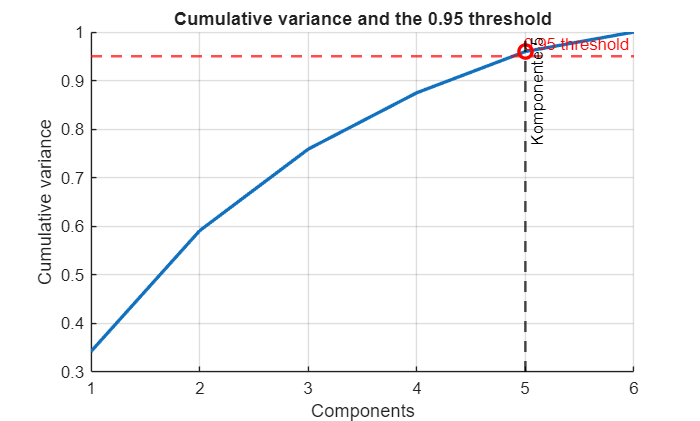

% Determine the number of components to retain based on explained variance:
threshold = 0.95; % 95% variance threshold
cumulativeVariance = cumsum(explainedVariance);
numComponents = find(cumulativeVariance >= threshold, 1, "first");

% Graphical representation of cumulative variance and threshold:
figure; hold on;
plot(cumulativeVariance, 'LineWidth', 2);
yline(threshold, '--r', '0.95 threshold', 'LineWidth', 1.5);
xline(numComponents, '--k', sprintf('Komponente %d', numComponents), 'LineWidth', 1.5);
plot(numComponents, cumulativeVariance(numComponents), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
xlabel('Components');
ylabel('Cumulative variance');
title('Cumulative variance and the 0.95 threshold');
grid on;


% Calculate the reduced feature matrix using the selected components:
reducedProjectedData = FeatureMatrix * V(:, 1:numComponents);
%reducedFeatureMatrix = U(:, 1:numComponents) * S(1:numComponents, 1:numComponents);
% Display the reduced feature matrix dimensions for verification
disp(size(reducedProjectedData));

    30     5



display(reducedProjectedData);

reducedProjectedData =    -0.1866    0.8436    0.5106   -0.8309   -0.1786
   -1.4226    0.0188   -0.3499    1.1782   -0.7075
   -0.7266   -0.0760   -0.1172   -1.6924    0.8066
   -2.1398    1.9619   -0.8255   -0.6587    0.3732
   -1.5151    0.7820   -0.1095    0.6393    0.0169
    0.9253    2.3071    1.4516    0.7031    0.0154
    0.4839   -1.2174    1.2034    0.8891    0.1868
   -0.6633   -2.6815   -1.2471    0.3853    0.4465
   -0.3916   -0.7762   -0.1798   -1.3971    1.0669
    1.5610    0.4388   -1.2219    0.7679    1.0116
   -2.8274   -1.4034   -0.2826   -0.5436   -1.3250
   -2.3079    0.5360   -0.4086    0.3858   -0.0156
   -0.5656    0.3206    0.1579   -2.0152   -0.9198
    0.5099    1.0473   -1.1775    0.3953   -0.1872
    2.7205   -0.8953   -1.6556    0.5664   -0.6953


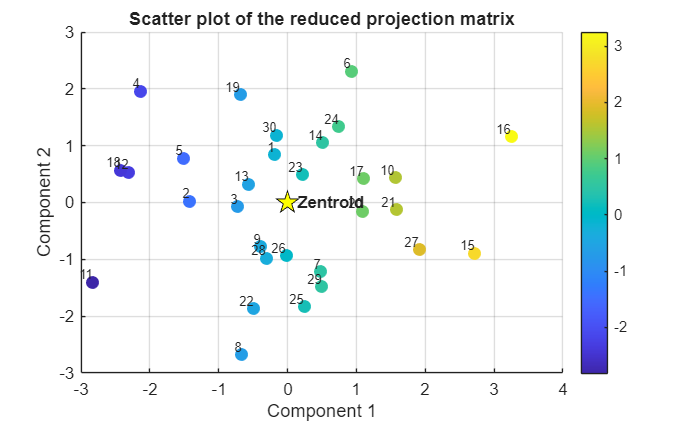


% Visualize the reduced feature matri
X = reducedProjectedData(:,1);
Y = reducedProjectedData(:,2);

figure;
scatter(X, Y, 60, X, 'filled');   % Färbung nach PC1
colorbar;
xlabel('Component 1');
ylabel('Component 2');
title('Scatter plot of the reduced projection matrix');
grid on;
hold on;

% --- Labels for each sample ---
for i = 1:length(X)
    text(X(i), Y(i), sprintf('%d', i), ...
         'VerticalAlignment','bottom', ...
         'HorizontalAlignment','right', ...
         'FontSize', 8);
end

% --- Calculate the centroid ---
centroidX = mean(X);
centroidY = mean(Y);

% --- Draw the centroid ---
plot(centroidX, centroidY, 'kp', 'MarkerSize', 14, 'MarkerFaceColor', 'y');
text(centroidX, centroidY, '  Zentroid', ...
     'VerticalAlignment','middle', ...
     'HorizontalAlignment','left', ...
     'FontWeight','bold');

hold off;

#### Comparison with OrthoFlow results:

%--------------------- Function Matchprojection --------------------------
function [X2_corrected, signs, corrMatrix] = matchProjection(X1, X2)
    % MATCHPROJECTION
    % Compares two projection matrices X1 and X2 (of the same dimensions)
    % and corrects the signs of X2 so that they match X1 as closely as possible.

    % Correlation between all pairs of columns:
    corrMatrix = corr(X1, X2);

    % Extract the sign from the diagonal:
    signs = sign(diag(corrMatrix));

    % Apply the sign to X2:
    X2_corrected = X2 .* signs';

    % Edition for educational purposes:
    fprintf("\n=== Comparison: MATLAB vs. OrthoFlow ===\n\n");
    maxAbsDiff = max(abs(X1(:) - X2_corrected(:)));
    meanAbsDiff = mean(abs(X1(:) - X2_corrected(:)));
    froSq = norm(X1 - X2_corrected, 'fro')^2;

    fprintf("Maximum absolute deviation: %.12e\n", maxAbsDiff);
    fprintf("Mean absolute deviation   : %.12e\n", meanAbsDiff);
    fprintf("Sum of squared deviations : %.12e\n", froSq);

    fprintf("\nSign per component:\n");
    disp(signs');

    fprintf("Correlation matrix (before correction):\n");
    disp(corrMatrix);
end
%-------------------------------------------------------------------------

% Reading the OrthoFlow-SVD output file dense_input.csv:
denseInputData = readtable("F:\C++ Projekte\OrthoFlow\dense_input.csv")

denseInputData = 30×7 table
      Var1         Var2        Var3         Var4        Var5        Var6         Var7   
    _________    ________    _________    ________    ________    _________    _________

      0.11202    -0.18663     -0.84364      0.5106     0.83089      0.17857     -0.52458
      0.16084     -1.4226    -0.018824    -0.34992     -1.1782      0.70746     -0.13071
    0.0063794    -0.72657     0.075969    -0.11724      1.6924     -0.80656     -0.54241
     0.020598     -2.1398      -1.9619    -0.82551     0.65869     -0.37323    -0.043653
      0.03579     -1.5151     -0.78199    -0.10952    -0.63931    -0.016945     -0.82177
      0.15808     0.92534      -2.3071      1.4515    -0.70308    -0.015353       0.6129
     0.072552     0.4

% Extract relevant columns from the table for further analysis:
DenseProjectionMatrix = table2array(denseInputData(:, 2:end));

[X2_corr, signs, corrMatrix] = matchProjection(projectedData, DenseProjectionMatrix);


=== Comparison: MATLAB vs. OrthoFlow ===

Maximum absolute deviation: 4.853174057518e-06
Mean absolute deviation   : 8.302724101160e-07
Sum of squared deviations : 4.210954558775e-10

Sign per component:
     1    -1     1    -1    -1    -1

Correlation matrix (before correction):
    1.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0000   -1.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0000   -0.0000    1.0000   -0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000   -1.0000    0.0000    0.0000
    0.0000    0.0000    0.0000   -0.0000   -1.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000   -1.0000




% End of Script
